# Homework #3

## Build a logistic regression model to predict heart disease

#### Import data and preview 

data1 = readtable("../cleveland_data_revised.xlsx");
head(data1,5)

ans = 5×14 table
    Age    SEX    chestPain    restingBP    cholest    highBloodSugar    ECG    maxHR    angina    ECGDepression    slopeST    fluoroscopy    thalliumTest    diseaseSeverity
    ___    ___    _________    _________    _______    ______________    ___    _____    ______    _____________    _______    ___________    ____________    _______________

    63      1         1           145         233            1            2      150       0            2.3            3            0              6          

#### Build model that predicts whether individual has heart disease.

data1 = rmmissing(data1);

X = data1{:,1:13};
Y = double(data1.diseaseSeverity > 0);   % convert logical to double
Y_cat = categorical(Y);     % convert double to category for mnrfit
[mdl1,~,stats1] = mnrfit(X,Y_cat);

#### Build model that predicts disease severity.

Y2 = data1.diseaseSeverity;
mdl2 = fitlm(X,Y2);

#### Evaluate both models using three-fold cross validation.

indices = crossvalind('kfold',size(data1,1),3);

accuracy = zeros(1,3);
precision = zeros(1,3);
recall = zeros(1,3);

rank = zeros(1,3);
RMSE = zeros(1,3);
prcnt_error = zeros(1,3);

for i = 1:3
    test = indices == i;
    train = ~test;
    
    Xtest = X(test,:);
    Ytest = Y(test,:);
    Ytest2 = Y2(test,:);
    
    probability = mnrval(mdl1,Xtest);
    Ypred = round(probability(:,2));
    accuracy(i) = sum(Ypred==Ytest)/length(Ypred);
    precision(i) = sum(Ypred==1 & Ytest==1)/sum(Ypred==1);
    recall(i) = sum(Ypred==1 & Ytest==1)/sum(Ytest==1);
    
    Ypred2 = predict(mdl2, Xtest);
    rank(i) = corr(Ytest2,Ypred2,"type","Spearman");
    RMSE(i) = sqrt(mean((Ypred2-Ytest2).^2));
    %prcnt_error(i) = mean((Ypred2-Ytest2) ./ Ytest2 * 100)
end

#### Model 1 Performance

mean(accuracy)

ans = 0.8485

mean(precision)

ans = 0.8496

mean(recall)

ans = 0.8175

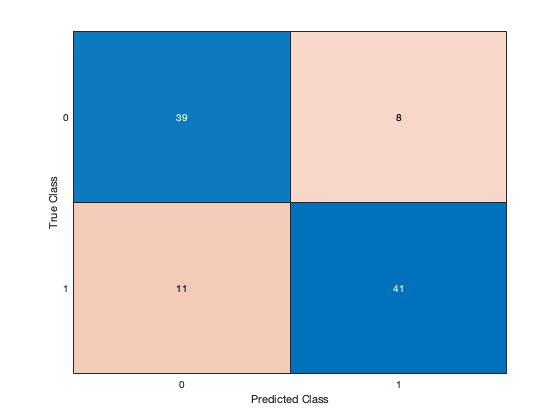

confusionchart(Ytest,Ypred);   % uses last cross-validation iteration

#### Model 2 Performance

mean(rank)

ans = 0.7501

mean(RMSE)

ans = 0.8095

%mean(prcnt_error)

#### Compare models to distribution of 100 random guesses using a t-test

guess_accuracy = zeros(100,1);
guess_RMSE = zeros(100,1);
for i = 1:100
    mdl1_guess = Y(randperm(length(Ytest)));
    mdl2_guess = Y2(randperm(length(Ytest2)));
    
    guess_accuracy(i,1) = sum(mdl1_guess == Ytest)/length(Ytest);
    guess_RMSE(i,1) = sqrt(mean((Ypred2-Ytest2).^2));
    %accuracy_guess2(i,1) = sum(mdl2_guess == Ytest2)/length(Ytest2);
end
mean(guess_accuracy)

ans = 0.4905

mean(guess_RMSE)

ans = 0.7990

[h_mdl1, p_mdl1] = ttest2(accuracy,guess_accuracy)

h_mdl1 = 1

p_mdl1 = 7.5711e-23

[h_mdl2, p_mdl2] = ttest2(RMSE,guess_RMSE)

h_mdl2 = 1

p_mdl2 = 1.5664e-06

#### Most important features from each model, based on p-value

Model 1

[p1,m1] = mink(stats1.p,5)

p1 =     0.0000
    0.0006
    0.0026
    0.0072
    0.0105


m1 =     13
    14
     4
     3
     1


% Must subtract 1 from index to account for intercept term
data1.Properties.VariableNames([12,13,3,2])

ans = 1×4 cell array
    {'fluoroscopy'}    {'thalliumTest'}    {'chestPain'}    {'SEX'}


Model 2

[p2,m2] = mink(mdl2.Coefficients.pValue,5)

p2 =     0.0000
    0.0000
    0.0008
    0.0011
    0.0348


m2 =     13
    14
     4
    11
     9


data1.Properties.VariableNames([12,13,3,10,8])

ans = 1×5 cell array
    {'fluoroscopy'}    {'thalliumTest'}    {'chestPain'}    {'ECGDepression'}    {'maxHR'}


## Brain cancer survival data set

#### Import and inspect data 

data2 = readtable("Top 100 Genes.xlsx");
tail(data2,5)

ans = 5×104 table
     PATIENT_ID     SurvivalDays    SurvivalDaysPF    Test     LIX1L       NEU4       TTC12       IFITM10      EIF3L       DGCR14      MRPS27     KHDRBS3      CCDC89       PHB2        TTLL1      PPAPDC1A     TNNC2        WWP2      C2orf27A       USE1        FCHSD2      EEF1G      C20orf196    RPL19P12     LYSMD1      OLIG1      ZNF780A      LUZP2       MYO15A       RPL3       PCBP3      C7orf53       TSSC1       

#### Create train and tests sets X and Y 

Xtrain = data2{data2.Test==0,5:end};
Xtest = data2{data2.Test==1,5:end};

Ytrain = data2{data2.Test==0,3};
Ytest = data2{data2.Test==1,3};


#### Build lasso model

[B1, Fit] = lasso(Xtrain,Ytrain,'CV',10); 
B1_coeff = B1(:,Fit.IndexMinMSE);
B1_intercept = Fit.Intercept(Fit.IndexMinMSE) 

B1_intercept = 459.5216

#### Build stepwise model

[B2,~,~,inmodel,stats] = stepwisefit(Xtrain,Ytrain);

Initial columns included: none
Step 1, added column 1, p=1.14656e-05
Step 2, added column 87, p=0.000780954
Step 3, added column 67, p=0.00203177
Step 4, added column 16, p=0.0131333
Step 5, added column 94, p=0.021837
Final columns included:  1 16 67 87 94 
    'Coeff'        'Std.Err.'    'Status'    'P'         
    [ 331.2930]    [ 61.5834]    'In'        [3.7580e-06]
    [  12.6648]    [ 29.8070]    'Out'       [    0.6733]
    [ -23.1072]    [ 37.5795]    'Out'       [    0.5423]
    [   7.9953]    [ 33.8602]    'Out'       [    0.8146]
    [  44.1486]    [ 72.8926]    'Out'       [    0.5483]
    [  75.1289]    [ 71.2068]    'Out'       [    0.2981]
    [ -84.6673]    [ 84.8098]    'Out'       [    0.3244]
    [  27.2049]    [ 38.5893]    'Out'       [    0.4851]
    [ -52.8482]    [ 29.3072]    'Out'       [    0.0793]
    [ -17.4918]    [ 88.8986]    'Out'       [    0.8451]
    [ -28.4037]    [ 65.8510]    'Out'       [    0.6687]
    [ -39.2505]    [ 43.8732]    'Out'       

#### Use models to predict survival (PFS). Calculate correlation and mean absolute error

Lasso

Ypred_lasso = Xtest * B1_coeff + B1_intercept;
r_lasso = corr(Ypred_lasso,Ytest)

r_lasso = 0.2259

avg_error_lasso = mean(abs(Ypred_lasso-Ytest))

avg_error_lasso = 281.1800

Stepwise

Ypred_step = Xtest(:,find(stats.PVAL < 0.05))*B2(find(stats.PVAL < 0.05)) + stats.intercept;
r_stepwise = corr(Ypred_step,Ytest)

r_stepwise = 0.4530

avg_error_stepwise = mean(abs(Ypred_step-Ytest))

avg_error_stepwise = 275.6031

## Compare regression methods with linear regession

#### Build linear regression model with top 15 correlated genes

% Find correlation of all 100 genes and then extract data for top 15 genes
r_100 = corr(Xtrain,Ytrain);
[r_15,index_15] = maxk(abs(r_100),15);

% Create new training and test sets with top 15 genes 
Xtrain_15 = Xtrain(:,index_15);
Xtest_15 = Xtest(:,index_15);

mdl = fitlm(Xtrain_15,Ytrain)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)     457.33     56.354      8.1153    5.9897e-09
    x1              213.75     120.73      1.7704      0.087166
    x2             -160.74     114.06     -1.4093       0.16939
    x3             -33.507     159.69    -0.20982       0.83527
    x4               174.4      195.9     0.89022       0.38068
    x5              31.944     170.59     0.18725       0.85277
    x6              180.64     128.12      1.4099        0.1692
    x7       

#### Predict survival (PFS) in test set and measure model accuracy 

Ypred_norm = predict(mdl,Xtest_15);

r_norm = corr(Ytest,Ypred_norm)

r_norm = 0.0677

avg_error = mean(abs(Ypred_norm-Ytest))

avg_error = 279.0284

#### Compare correlation and number of features of 3 methods 

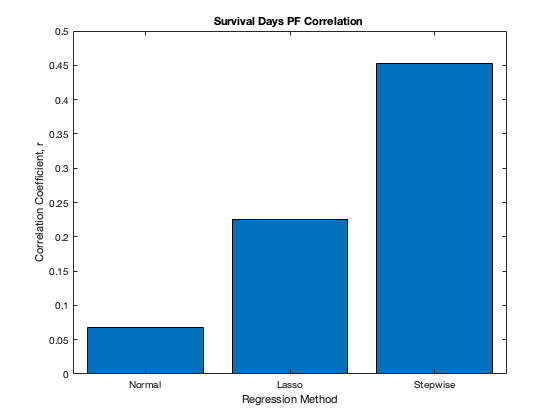

% Create labels for bar graphs
x = categorical({'Normal','Lasso','Stepwise'});
x = reordercats(x,{'Normal','Lasso','Stepwise'});

% Correlation bar graph. 
bar(x,[r_norm,r_lasso,r_stepwise])
xlabel("Regression Method")
ylabel("Correlation Coefficient, r")
title("Survival Days PF Correlation ")

% Find number of features in each model
size_lin_reg = size(mdl.Coefficients,1)-1   % subtract 1 for intercept term

size_lin_reg = 15

size_lasso = length(B1_coeff)

size_lasso = 100

size_stepwise = length(find(stats.PVAL < 0.05))

size_stepwise = 5

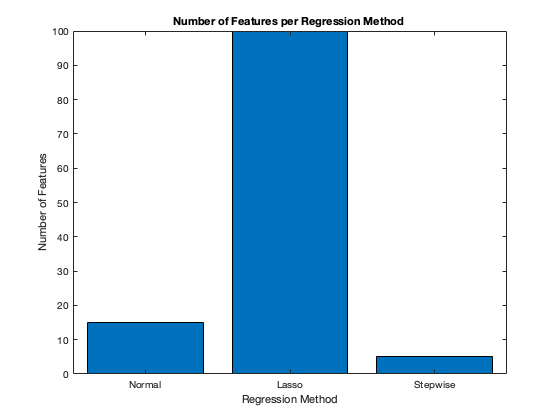

% Number of features bar graph
bar(x,[size_lin_reg,size_lasso,size_stepwise])
xlabel("Regression Method")
ylabel("Number of Features")
title("Number of Features per Regression Method ")